# 1RC model verify

close all
clear
clc

% 脉冲计算
% load('theta_plusfitting_1s.mat'); % 1s
load('theta_plusfitting_2s_10.mat'); % 2s
% load('theta_plusfitting_3s.mat'); % 3s
% load('theta_plusfitting_4s.mat'); % 4s

% 全局辨识
% load('theta_c_20211204_2.mat'); % 全局拟合
% load('theta_d_20211204_2.mat');
% load('theta_allfittig_20211213_3.mat')
thetatable = [0,0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1];

% OCV-SOC 与 迟滞参数设置
load('ocvsoc1000.mat');
load('Hocv_dynamic.mat');
% load('Hocv.mat')

% 验证工况设置
Cap = 33.804*3600; % A*S
load('DST_Data.mat');
% load('Charge_0C5.mat');
% refsoc = Capacity/Capacity(end);
% load('Discharge_0C5.mat');

% 迟滞参数设置
hycoff = 20;

% 初始SOC恒流充电反查表
% a = ocvAverage1000 - Ut(1);
% [bb,cc] = min(abs(a));
% refsoc0 = soctable1000(cc);
% refsoc_correct =  refsoc+refsoc0;

% 计算OCV
ocv = interp1(soctable1000,ocvAverage1000,refsoc,'linear');
deltaTime = diff(Time);

% 初始化
R0 = zeros(length(I),1);
u0 = zeros(length(I),1);
R1 = zeros(length(I),1);
tao1 = zeros(length(I),1);
u1 = zeros(length(I),1); % 初始化
h = zeros(length(I),1);
h(1) = 0;

% 第一步迭代
R0(1) = interp1(thetatable,theta_d(1,:),refsoc(1)) * (I(1) >= 0) + interp1(thetatable,theta_c(1,:),refsoc(1)) * (I(1) < 0);
R1(1) = interp1(thetatable,theta_d(2,:),refsoc(1)) * (I(1) >= 0) + interp1(thetatable,theta_c(2,:),refsoc(1)) * (I(1) < 0);
tao1(1) = interp1(thetatable,theta_d(3,:),refsoc(1)) * (I(1) >= 0) + interp1(thetatable,theta_c(3,:),refsoc(1)) * (I(1) < 0);
H(1) = interp1(soctable_hys,Hocv,refsoc(1),'linear');

% 第二步迭代
for index = 2:length(I)
    R0(index) = interp1(thetatable,theta_d(1,:),refsoc(index)) * (I(index) >= 0) + interp1(thetatable,theta_c(1,:),refsoc(index)) * (I(index) < 0);
    R1(index) = interp1(thetatable,theta_d(2,:),refsoc(index)) * (I(index) >= 0) + interp1(thetatable,theta_c(2,:),refsoc(index)) * (I(index) < 0);
    tao1(index) = interp1(thetatable,theta_d(3,:),refsoc(index)) * (I(index) >= 0) + interp1(thetatable,theta_c(3,:),refsoc(index)) * (I(index) < 0);
    
    u0(index) = I(index) * R0(index);
    u1(index) = exp(-deltaTime(index-1)/(tao1(index-1)))*u1(index-1) + I(index-1)*R1(index-1)*(1-exp(-deltaTime(index-1)/(tao1(index-1)))); % 使用上一步参数
    
%     u1(index) = exp(-deltaTime(index-1)/(tao1(index)))*u1(index-1) + I(index-1)*R1(index)*(1-exp(-deltaTime(index-1)/(tao1(index)))); % 使用本步参数
%     u2(index) = exp(-deltaTime(index-1)/(tao2(index)))*u2(index-1) + I(index-1)*R2(index)*(1-exp(-deltaTime(index-1)/(tao2(index)))); % 使用本步参数
    % 使用上一步参数还是这一步参数？
    H(index) = interp1(soctable_hys,Hocv,refsoc(index),'linear');
    h(index) = h(index-1) * exp(-abs(hycoff*I(index-1)*deltaTime(index-1)/Cap)) + (1 - exp(-abs(hycoff*I(index-1)*deltaTime(index-1)/Cap)) ) * ...
        ((-H(index))*(I(index)>0) + (H(index)) * (I(index)<=0));
end

Ut_est = ocv - u0 - u1  + h ;
err = Ut - Ut_est;
RMSE = (sum(err.^2)/length(err))^0.5

RMSE = 0.0134

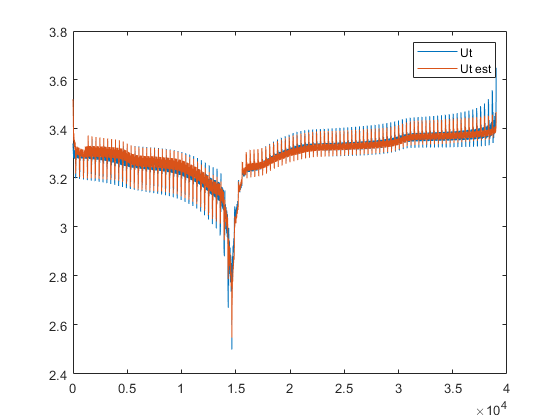


figure,plot(Ut), hold on, plot(Ut_est);
    legend('Ut','Ut est');

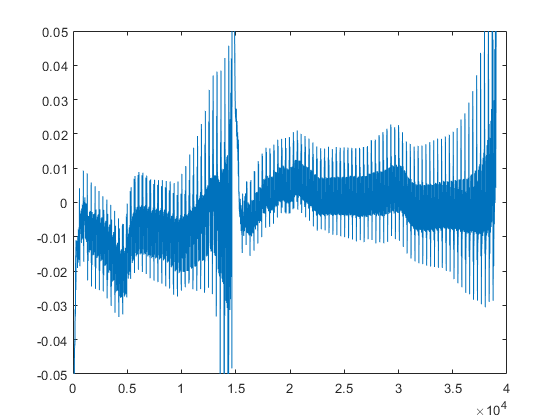


figure, plot(err);
ylim([-0.05,0.05]);


figure,
yyaxis left
plot(ocv),hold on,plot(Ut),plot(Ut_est);

yyaxis right
plot(h), hold on, plot(-u1);
legend('ocv','Ut','Ut_est','h','-u1');


RMSE2 = (sum(err(1000:7000).^2)/length(err(1000:7000)))^0.5

RMSE2 = 0.0113